# Analysis Scripts and Methods

To avoid unnecessary complications in this script, it is written to do analysis for a uniform **DVD prior on the enitre dataset **

and the **tolerance-based prior on the very intolerant bin only** rather than showing every bin/prior calculation. To recreate the 

analysis in the main text, the steps can be repeated for each bin from the **Prior Calculation** section through the rest of the script.     

## Load Variants

% Clear any data currently in the Matlab environment
clear, close all
% Load variants into a table and print their classification statistics
filename = 'correct_var.csv'; % Specify the filename for the variants data
variant_table = read_and_clean_variants(filename); % Call the function to read and clean the data

       Classification       GroupCount    Percent
    ____________________    __________    _______

    Benign                       2820     0.74066
    Benign*                        68     0.01786
    Likely benign               65491      17.201
    Likely pathogenic            3205     0.84178
    Pathogenic                   6660      1.7492
    Unknown significance    3.025e+05      79.449



## Calculate the likelihood ratios for each score 

## (CADD, REVEL, and folding free energy difference)

% CADD likelihood ratios for the variants based on a CADDPhred column
% midpoints are returned for plotting later
score_column_name = 'CADDPhred'; % Specify the score column name
max_score = 40; % Define the maximum score for binning
nbins = 10; % Define the number of bins
[likelihood_benign_CADD, likelihood_pathogenic_CADD, cadd_midpoints] = calculate_likelihood_ratios(variant_table, score_column_name, max_score, nbins);

% REVEL likelihood ratios for the variants based on a Revel column
score_column_name = 'Revel'; % Specify the score column name
max_score = 1.0; % Define the maximum score for binning
nbins = 10; % Define the number of bins
[likelihood_benign_REVEL, likelihood_pathogenic_REVEL, revel_midpoints] = calculate_likelihood_ratios(variant_table, score_column_name, max_score, nbins);

% Folding free energy difference likelihood ratios for the variants based on a x_ddG_ column
score_column_name = 'x_ddG_'; % Specify the score column name
max_score = 6.5; % Define the maximum score for binning
nbins = 10; % Define the number of bins
[likelihood_benign_ddG, likelihood_pathogenic_ddG, ddG_midpoints] = calculate_likelihood_ratios(variant_table, score_column_name, max_score, nbins);

## Bin variants base on o/e score

% The o/e bin edges defined for this work
% The trailing edge of each bin is exclusive.
% Any genes with o/e scores will be placed in a no tolerance bin
% (X-linked/MT for this work)
% Bin labels will be added as an additional column in the variant table



variant_table_bin = bin_variants(variant_table);

Iteration 50000.
Iteration 100000.
Iteration 150000.
Iteration 200000.
Iteration 250000.
Iteration 300000.
Iteration 350000.


binCounts = table(categorical(variant_table_bin.Bin), 'VariableNames',{'Bin'});
binT= groupcounts(binCounts,"Bin");
disp(binT)

           Bin           GroupCount    Percent
    _________________    __________    _______

    Average Tolerance     2.09e+05     54.895 
    Intolerant               64991      17.07 
    No Tolerance             19568     5.1395 
    Tolerant                 87175     22.896 



## Prior Calculation

% This script will use the entire DVD and very intolerant bin as example
% cases. Repeat steps from this section on to recreate the entire analysis
% from the main text.

% Collect variants in the very intolerant bin
intolerant_variants = variant_table_bin(contains(variant_table_bin.Bin,'Intolerant'),:);
average_variants = variant_table_bin(contains(variant_table_bin.Bin,'Average'),:);
tolerant_variants = variant_table_bin(contains(variant_table_bin.Bin,'Tolerant'),:);
none_variants = variant_table_bin(contains(variant_table_bin.Bin,'No Tolerance'),:);
% Display the variant classification counts in the very intolerant bin
counts = table(categorical(intolerant_variants.Classification), 'VariableNames',{'Classification'});
count = groupcounts(counts,"Classification");
disp(count)

       Classification       GroupCount    Percent 
    ____________________    __________    ________

    Benign                      309        0.47545
    Benign*                       6       0.009232
    Likely benign              6510         10.017
    Likely pathogenic           795         1.2232
    Pathogenic                 1561         2.4019
    Unknown significance      55810         85.873





% Calculate the uniform DVD prior
[uniform_DVD_prior_pathogenic,  uniform_DVD_prior_benign] = calculate_priors(variant_table)

uniform_DVD_prior_pathogenic = 0.1443

uniform_DVD_prior_benign = 0.8739


% Calculate the very intolerant prior
[intolerant_prior_pathogenic,  intolerant_prior_benign] = calculate_priors(intolerant_variants)

intolerant_prior_pathogenic = 0.3452

intolerant_prior_benign = 0.7434

[average_prior_pathogenic,  average_prior_benign] = calculate_priors(average_variants)

average_prior_pathogenic = 0.1203

average_prior_benign = 0.8926

[tolerant_prior_pathogenic,  tolerant_prior_benign] = calculate_priors(tolerant_variants)

tolerant_prior_pathogenic = 0.0955

tolerant_prior_benign = 0.9128

## Genetic Tool Analysis

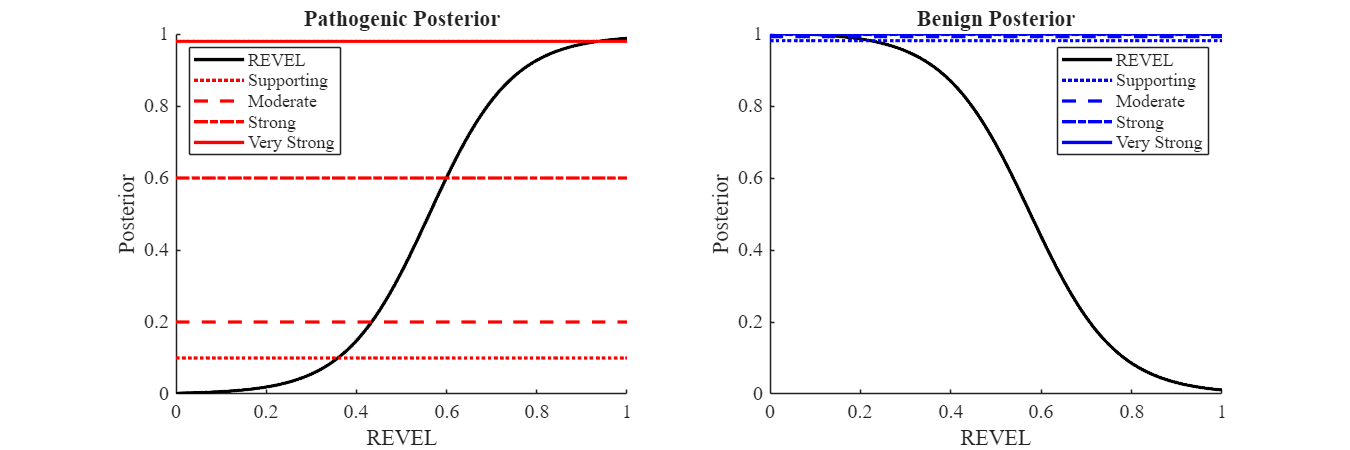

uniform_DVD_thresholds = 1×8 table
    B Very Strong    B Strong    B Moderate    B Supporting    P Supporting    P Moderate    P Strong    P Very Strong
    _____________    ________    __________    ____________    ____________    __________    ________    _____________

      0.072072       0.096096     0.16416        0.22322         0.35936        0.43343       0.5996        0.93794   


% Use calculate genetic tool thresholds to calculate the genetic thresholds
% and plot the pathogenic and benign posterior plots
% NaN indicates that evidence level was not reached
uniform_DVD_thresholds = calculate_genetic_tool_thresholds(uniform_DVD_prior_pathogenic, ...
    uniform_DVD_prior_benign,likelihood_pathogenic_REVEL,likelihood_benign_REVEL,revel_midpoints, 1.0,'REVEL')

intolerant_thresholds = 1×8 table
    B Very Strong    B Strong    B Moderate    B Supporting    P Supporting    P Moderate    P Strong    P Very Strong
    _____________    ________    __________    ____________    ____________    __________    ________    _____________

         NaN           NaN        0.05005        0.13814         0.26727        0.33834      0.49449        0.82583   


intolerant_thresholds = calculate_genetic_tool_thresholds(intolerant_prior_pathogenic, ...
    intolerant_prior_benign,likelihood_pathogenic_REVEL,likelihood_benign_REVEL,revel_midpoints, 1.0,'REVEL')

average_thresholds = 1×8 table
    B Very Strong    B Strong    B Moderate    B Supporting    P Supporting    P Moderate    P Strong    P Very Strong
    _____________    ________    __________    ____________    ____________    __________    ________    _____________

      0.086086       0.11011      0.17818        0.23724         0.37538        0.45145      0.61962        0.94695   


average_thresholds = calculate_genetic_tool_thresholds(average_prior_pathogenic, ...
    average_prior_benign,likelihood_pathogenic_REVEL,likelihood_benign_REVEL,revel_midpoints, 1.0,'REVEL')

tolerant_thresholds = 1×8 table
    B Very Strong    B Strong    B Moderate    B Supporting    P Supporting    P Moderate    P Strong    P Very Strong
    _____________    ________    __________    ____________    ____________    __________    ________    _____________

      0.096096       0.12212      0.19419        0.25526          0.3964        0.47447      0.64565        0.95395   


tolerant_thresholds = calculate_genetic_tool_thresholds(tolerant_prior_pathogenic, ...
    tolerant_prior_benign,likelihood_pathogenic_REVEL,likelihood_benign_REVEL,revel_midpoints, 1.0,'REVEL')

% Use predict class to use genetic tool thresholds to predict
% classifications for variants and calculate the accuracy, sensitivity, and
% specificity for the set of variants and thresholds provided at the
% desired evidence level.
[i_predicted_pathogenic, i_predicted_benign, i_predicted_uncertain] = predict_class(intolerant_variants, intolerant_thresholds,'Revel','very strong');
[a_predicted_pathogenic, a_predicted_benign, a_predicted_uncertain] = predict_class(average_variants, average_thresholds,'Revel','very strong');
[t_predicted_pathogenic, t_predicted_benign, t_predicted_uncertain] = predict_class(tolerant_variants, tolerant_thresholds,'Revel','very strong');
[none_predicted_pathogenic, none_predicted_benign, none_predicted_uncertain] = predict_class(none_variants, uniform_DVD_thresholds,'Revel','very strong');
% Combine results for the three bins and x linked genes into one table and
% calculate performance statistics on predictions
combined_predicted_pathogenic = [i_predicted_pathogenic; a_predicted_pathogenic; t_predicted_pathogenic; none_predicted_pathogenic];
combined_predicted_benign = [i_predicted_benign; a_predicted_benign; t_predicted_benign; none_predicted_benign];
combined_predicted_uncertain = [i_predicted_uncertain; a_predicted_uncertain; t_predicted_uncertain;none_predicted_pathogenic];
[accuracy, sensitivity, specificity] = calculate_performance(combined_predicted_pathogenic,combined_predicted_benign, combined_predicted_uncertain)

% Calculate accuracy, sensitivity, and specificity for the uniform
% thresholds
[uniform_predicted_pathogenic, uniform_predicted_benign, uniform_predicted_uncertain] = predict_class(variant_table, uniform_DVD_thresholds,'Revel','strong');

## Biophysics-Informed Analysis

% Calculate the REVEL x ddG likelihood
revel_ddG_likelihood = likelihood_pathogenic_REVEL.* likelihood_pathogenic_ddG';

% Fit the posterior to a curve and plots scatterplots with prioritized VUS
% with fit_likelihood
curve_fit = fit_likelihood(variant_table_bin, revel_midpoints,ddG_midpoints,revel_ddG_likelihood,uniform_DVD_prior_pathogenic,1, 1.0, 'Revel');
% Select variants that fall above the calculated threshold and save into a
% table that can be written to a csv for closer inspection.
uniform_DVD_prioritized_variants = prioritize(variant_table_bin,curve_fit,1.0,'Revel');

% Same as above but with the very intolerant bin
curve_fit = fit_likelihood(intolerant_variants, revel_midpoints,ddG_midpoints,revel_ddG_likelihood,intolerant_prior_pathogenic,1, 1.0, 'Revel');
very_intolerant_prioritized_variants = prioritize(intolerant_variants,curve_fit,1.0,'Revel');

% Reads all variants into a table and prints the classification breakdown.
% It will also remove any in-dels accidentally included in the missense
% variant collection. 
% Input the csv file containing the variants
% Returns a table containing all the variant information in the CSV
function variant_table = read_and_clean_variants(filename)
    variant_table = readtable(filename);
    % Remove del-ins variants from overall list 
    X = contains(variant_table.Protein_Change,'del');
    variant_table(X,:) = [];
    % Total variants and breakdown by classification
    counts = table(categorical(variant_table.Classification), 'VariableNames',{'Classification'});
    count = groupcounts(counts,"Classification");
    disp(count)
end

% Calculate the likelihood ratios [Benign, Pathogenic] for a given max
% score given in equally spaced bins. 10 bins were used for this work. The
% max score will bin everything above the max into the last bin. This is
% meant to handle outlier score values.
% Input the variant table, score column name, max score, and number of bins desired.
% Returns are array of likelihoods for benign and pathogenic variants and
% midpoints using for the calculations (needed for plotting later)
function [likelihood_benign, likelihood_pathogenic, midpoints] = calculate_likelihood_ratios(variant_table, score_column_name, max_score, nbins) 
    % Make tables of all pathogenic and benign variants
    pathogenic_variants = variant_table(contains(variant_table.Classification, "athogenic"),:);
    benign_variants = variant_table(contains(variant_table.Classification, "enign"),:);

    % Calculate the pathogenic and benign prior odds
    prior_pathogenic = height(pathogenic_variants)/(height(pathogenic_variants)+height(benign_variants));
    prior_benign = height(benign_variants)/(height(pathogenic_variants)+height(benign_variants));

    % Gather the scores for pathogenic and benign variants and set all
    % scores higher than the max score to the max score  for binning
    % purposes.
    pathogenic_scores = pathogenic_variants{:,score_column_name};
    benign_scores = benign_variants{:,score_column_name};
    pathogenic_scores(pathogenic_scores>max_score)=max_score;
    benign_scores(benign_scores>max_score)=max_score;

    % Use histcounts to determine the counts in each bin and the centers
    % for the bins. The centers will be the same for both pathogenic and
    % benign likelihood calculations.
    [counts_pathogenic, centers] = histcounts(pathogenic_scores, nbins);
    [counts_benign, centers] = histcounts(benign_scores,centers);
    midpoints = centers(1:end-1) + diff(centers) / 2;

    % Calculate the probability of benign or pathogenic variants occuring
    % in each bin
    prob_pathogenic_score = counts_pathogenic./(height(pathogenic_variants)+height(benign_variants))/prior_pathogenic;
    prob_benign_score = counts_benign./(height(pathogenic_variants)+height(benign_variants))/prior_benign;
    
    % Return a likelihood ratio for each bin
    likelihood_pathogenic = prob_pathogenic_score./prob_benign_score;
    likelihood_benign = prob_benign_score./prob_pathogenic_score;
end

% Bin variants in by their o/e (tolerance) scores. The bins are hard coded
% to match the bins established in this work but could be updated in this
% function
% Input is the variant table
% Returns a new table with a Bin column added to variant table
function variant_table = bin_variants(variant_table)
    
    % Bin the variants based on the o/e scores and assign bin labels
    o_e_bin_edges = [0.1, 0.80, 1.00, 2.0];
    bin_labels = { 'Intolerant','Average Tolerance', 'Tolerant','No Tolerance'};
    
    % Create an empty array to fill with new bin labels
    bin = repmat({''},height(variant_table),1);
    for variant = 1:height(variant_table)
        geneOE = variant_table(variant,:).o_e;
        
        % Print progress for every 50K variants the loops iterates through
        if mod(variant, 50000) == 0
                    fprintf('Iteration %d.\n', variant);
        end

        % Determine the bin label give the o/e score
        if geneOE >= o_e_bin_edges(1) && geneOE < o_e_bin_edges(2)
            bin(variant,:) = cellstr(bin_labels(1));
        elseif geneOE >= o_e_bin_edges(2) && geneOE < o_e_bin_edges(3)
            bin(variant,:) = cellstr(bin_labels(2));
        elseif geneOE >= o_e_bin_edges(3) && geneOE < o_e_bin_edges(4)
            bin(variant,:) = cellstr(bin_labels(3));
        else 
            bin(variant,:) = cellstr(bin_labels(4));
        end
    end
    
    % Add a new column with label Bin and the bin labels to the variant
    % table
    variant_table.Bin = bin;
end

% Calculates the prior odds of pathogenicity and prior probability of being benign
% Input is a variant table
% Returns the prior odds of pathogenicity and prior probability of being
% benign
function [prior_pathogenic, prior_benign] = calculate_priors(variant_table)
    pathogenic_variants = variant_table(contains(variant_table.Classification, "athogenic"),:);
    benign_variants =  variant_table(contains(variant_table.Classification, "enign"),:);
    pathogenic_counts = height(pathogenic_variants);
    benign_counts = height(benign_variants);
    probability_pathogenic = pathogenic_counts / (pathogenic_counts+benign_counts);
    probability_benign = benign_counts / (pathogenic_counts+benign_counts);
    prior_pathogenic = probability_pathogenic / (1-probability_pathogenic);
    prior_benign = probability_benign;
end

% Calculate genetic tool thresholds and plot the posterior vs score and the
% evidence level cutoffs. 
% Input pathogenic prior, benign prior, pathogenic likelihood, benign
% likelihood, midpoints from the likelihood calculations, the max score,
% and the label for the score (i.e. 'CADD')
% Returns a table of pathogenic and benign cutoffs for the bin and plots of
% posterior curves 
function threshold_table = calculate_genetic_tool_thresholds(prior_pathogenic, prior_benign, likelihood_pathogenic, likelihood_benign, ...
                                                                                                    midpoints,max_score, score_label)
    % Lines for the different cutoffs in pejaver (supporting etc)
    supp = zeros(1000,1) + 0.1;
    mod = zeros(1000,1) + 0.2;
    strong = zeros(1000,1) + 0.6;
    vs = zeros(1000,1) + 0.98;
    supp_b = zeros(1000,1) + 0.9812;
    mod_b = zeros(1000,1) + 0.9921;
    strong_b = zeros(1000,1) + 0.9986;
    vs_b = zeros(1000,1) + 1.0;

    % Calculate the posterior vs score curve
    posterior_pathogenic = (likelihood_pathogenic.*prior_pathogenic)./((likelihood_pathogenic-1).*prior_pathogenic + 1);
    posterior_benign = (likelihood_benign.*prior_benign)./((likelihood_benign-1).*prior_benign + 1);

    % Fit a curve to the posteriors and interoplate points
    pathogenic_curve = fit(midpoints',posterior_pathogenic','logistic');
    interp_x = linspace(0,max_score,1000);
    path_posterior_interp = pathogenic_curve(interp_x);

    benign_curve = fit(midpoints',posterior_benign','logistic');
    ben_posterior_interp = benign_curve(interp_x);  

    % Calculate the pathogenic thresholds
    % Very Strong
    vs_diff = path_posterior_interp - 0.98;
    vs_cutoff_min = min(abs(vs_diff));
    idx = abs(vs_diff) == vs_cutoff_min;
    vs_path = interp_x(idx);
    if vs_path==max_score
        vs_path = NaN;
    end
    % Strong
    s_diff = path_posterior_interp - 0.6;
    s_cutoff_min = min(abs(s_diff));
    idx = abs(s_diff) == s_cutoff_min;
    s_path = interp_x(idx);
    if s_path==max_score
        s_path = NaN;
    end
    % Moderate
    mod_diff = path_posterior_interp - 0.2;
    mod_cutoff_min = min(abs(mod_diff));
    idx = abs(mod_diff) == mod_cutoff_min;
    mod_path =interp_x(idx);
    if mod_path==max_score
        mod_path = NaN;
    end
    % Supporting
    supp_diff = path_posterior_interp - 0.1;
    supp_cutoff_min = min(abs(supp_diff));
    idx = abs(supp_diff) == supp_cutoff_min;
    supp_path = interp_x(idx);
    if supp_path==max_score
        supp_path = NaN;
    end

    % Calculate the benign thresholds
    % Very Strong
    vs_diff = ben_posterior_interp - 1.0;
    vs_cutoff_min = min(abs(vs_diff));
    idx = abs(vs_diff) == vs_cutoff_min;
    vs_benign = interp_x(idx);
    if vs_benign==0
        vs_benign = NaN;
    end
    % Strong
    s_diff = ben_posterior_interp - 0.9986;
    s_cutoff_min = min(abs(s_diff));
    idx = abs(s_diff) == s_cutoff_min;
    s_benign = interp_x(idx);
    if s_benign==0
        s_benign = NaN;
    end
    % Moderate
    mod_diff = ben_posterior_interp - 0.9921;
    mod_cutoff_min = min(abs(mod_diff));
    idx = abs(mod_diff) == mod_cutoff_min;
    mod_benign = interp_x(idx);
    if mod_benign==0
        mod_benign = NaN;
    end
    % Supporting
    supp_diff = ben_posterior_interp - 0.9812;
    supp_cutoff_min = min(abs(supp_diff));
    idx = abs(supp_diff) == supp_cutoff_min;
    supp_benign = interp_x(idx);
    if supp_benign==0
        supp_benign = NaN;
    end
    
    % Plot the posterior curves
    f = figure('Position', [100 100 1080 360]);
    subplot(1,2,1)
    plot(interp_x, path_posterior_interp, 'k', interp_x, supp, 'r:', interp_x, mod, 'r--',interp_x, strong, 'r-.',interp_x, vs, 'r', 'LineWidth',2.0)
    box off;
    xlabel(score_label,'FontName', 'Times New Roman' , "FontSize", 11)
    ylabel('Posterior','FontName', 'Time New Roman' , "FontSize", 11)
    legend(score_label,'Supporting', 'Moderate', 'Strong', 'Very Strong', "Location","northwest")
    title("Pathogenic Posterior")
    set(gca,'FontSize',12, 'FontName', 'Times New Roman')
    xlim([0 max_score])
    ylim([0 1])
    
    subplot(1,2,2)
    plot(interp_x, ben_posterior_interp, 'k', interp_x, supp_b, 'b:', interp_x, mod_b, 'b--',interp_x, strong_b, 'b-.',interp_x, vs_b, 'b', 'LineWidth',2.0)
    box off;
    xlabel(score_label,'FontName', 'Times New Roman' , "FontSize", 11)
    ylabel('Posterior','FontName', 'Time New Roman' , "FontSize", 11)
    legend(score_label,'Supporting', 'Moderate', 'Strong', 'Very Strong', "Location","northeast")
    title("Benign Posterior")
    set(gca,'FontSize',12, 'FontName', 'Times New Roman')
    xlim([0 max_score])
    ylim([0 1])
    
    thresholds = [vs_benign, s_benign, mod_benign, supp_benign, supp_path, mod_path, s_path, vs_path];
    threshold_table = array2table(thresholds, 'VariableNames',{'B Very Strong','B Strong','B Moderate','B Supporting','P Supporting','P Moderate','P Strong','P Very Strong'});

end

% Use genetic tool thresholds to predict variant classification. Predict
% class will use calculated thresholds unless the evidence type selected is
% not reach, it will then revert to using the published thresholds from
% pejaver et al. 
% Input the variant table, the calculated thresholds, the scores column
% name, and the evidence strength desired
% Return all variants predicted pathogenic, all variants predicted benign,
% and all variants that fall between the benign and pathogenic threshold.
% Print the accuracy, sensitivity, and specificity where variants that are
% in the uncertain region count as incorrectly classified. 
function [pathogenic_variants,benign_variants,uncertain_variants] = predict_class(variant_table, thresholds,column_name,evidence_strength)
    % Thresholds in Pejaver et al
    % We only include CADD and REVEL since they were evaluated in this
    % work. Including another score is possible by making a new array with
    % the thresholds and making the input score_column match the third word
    % in the array name. Array should match [very strong benign, strong
    % benign, moderate benign, supporting benign, supporting pathogenic,
    % moderate pathogenic, strong pathogenic, very strong pathogenic].
    pejaver_thresholds_CADDPhred = [NaN, 0.15, 17.3, 22.7, 25.2, 28.1, NaN, NaN];
    pejaver_thresholds_Revel = [0.003, 0.016, 0.183, 0.290, 0.644, 0.773, 0.932, NaN];
    
    % Use the given evidence level to match the threshold needed
    evidence_labels = {'very strong','strong','moderate','supporting'};
    thresholds = table2array(thresholds);
    idx_b = find(strcmp(evidence_labels,evidence_strength));
    idx_p = 8 - idx_b + 1;

    benign_threshold = thresholds(:,idx_b);
    pathogenic_threshold = thresholds(:,idx_p);

    % Revert to Pejaver et al thresholds when benign/pathogenic does not
    % reach to designated evidence level
    if isnan(benign_threshold)
        variable_name = strcat('pejaver_thresholds_',column_name);
        pejaver_thresholds = eval(variable_name);
        benign_threshold = 0.0;
    end

    if isnan(pathogenic_threshold)
        variable_name = strcat('pejaver_thresholds_',column_name);
        pejaver_thresholds = eval(variable_name);
        pathogenic_threshold = 1.0;
    end

    % Create a logical array for all classifications that will be set true
    % if the variant reaches the threshold
    benign_variants_logical = false(height(variant_table),1);
    pathogenic_variants_logical = false(height(variant_table),1);
    uncertain_variants_logical = false(height(variant_table),1);

    % Check variant scores against thresholds 
    for variant_index = 1:height(variant_table)
        if mod(variant_index, 50000) == 0
            fprintf('Iteration %d.\n', variant_index);
            % You can also display other variables or results here
            % disp(someVariable);
        end
        variant = variant_table(variant_index,:);
        score = variant{:,column_name};
        
        if score > pathogenic_threshold
            pathogenic_variants_logical(variant_index,:) = true;
        elseif score < benign_threshold
            benign_variants_logical(variant_index,:) = true;
        else
            uncertain_variants_logical(variant_index,:) = true;
        end
    end

    % Pull the selected variants for each classification
    pathogenic_variants = variant_table(pathogenic_variants_logical,:);
    benign_variants = variant_table(benign_variants_logical,:);
    uncertain_variants = variant_table(uncertain_variants_logical,:);

    % Calculate accuracy, sensitivity, and specificity with calculate
    % performance function
    [accuracy, sensitivity, specificity] = calculate_performance(pathogenic_variants,benign_variants, uncertain_variants)
    
end

% Calculates the accuracy, sensitivity, and specificity for a tables of
% predicted variants. The input is 3 tables in order of predicted
% pathogenic variants, predicted benign variants, and uncertain variants
% and the output is an accuracy, sensitivity, and specificity 
function [accuracy, sensitivity, specificity] = calculate_performance(pathogenic_variants, benign_variants, uncertain_variants)
    % Compared the labelled variants to the predicted
    % classification
    pathogenic_counts = table(categorical(pathogenic_variants.Classification), 'VariableNames',{'Classification'});
    predicted_pathogenic = groupcounts(pathogenic_counts,"Classification");
    benign_as_pathogenic = predicted_pathogenic(contains(string(predicted_pathogenic.Classification),"enign"),:);
    pathogenic_as_pathogenic = predicted_pathogenic(contains(string(predicted_pathogenic.Classification),"athogenic"),:);
    wrong_benign = sum(benign_as_pathogenic.GroupCount);
    correct_pathogenic = sum(pathogenic_as_pathogenic.GroupCount);

    benign_counts = table(categorical(benign_variants.Classification), 'VariableNames',{'Classification'});
    predicted_benign = groupcounts(benign_counts,"Classification");
    pathogenic_as_benign = predicted_benign(contains(string(predicted_benign.Classification),"athogenic"),:);
    benign_as_benign = predicted_benign(contains(string(predicted_benign.Classification),"enign"),:);
    wrong_pathogenic = sum(pathogenic_as_benign.GroupCount);
    correct_benign = sum(benign_as_benign.GroupCount);

    uncertain_counts = table(categorical(uncertain_variants.Classification), 'VariableNames',{'Classification'});
    predicted_uncertain = groupcounts(uncertain_counts,"Classification");
    pathogenic_as_uncertain = predicted_uncertain(contains(string(predicted_uncertain.Classification),"athogenic"),:);
    benign_as_uncertain = predicted_uncertain(contains(string(predicted_uncertain.Classification),"enign"),:);
    uncertain_pathogenic = sum(pathogenic_as_uncertain.GroupCount);
    uncertain_benign = sum(benign_as_uncertain.GroupCount);

    false_pathogenic = wrong_pathogenic + uncertain_pathogenic;
    false_benign = wrong_benign + uncertain_benign;
    true_pathogenic = correct_pathogenic;
    true_benign = correct_benign;

    % Calculate accuracy, sensitivity, and specificity
    accuracy = (correct_pathogenic + correct_benign) / (false_pathogenic + false_benign + correct_benign + correct_pathogenic);
    sensitivity = correct_pathogenic / (false_pathogenic + correct_pathogenic);
    specificity = correct_benign / (false_benign + correct_benign);
end

% Calculate the biophysics informed thresholds using curve fits to where
% the posterior reaches very strong evidence. 
% Input the variant table, midpoints for the score used and ddG, the
% likelihood (combined), the prior, the degree to fit the polynomial (often
% 2 fo CADD and 1 for REVEL), the max score for the tool used, and the
% column label for the score (i.e. CADDPhred, Revel, etc)
% Returns the fit polynomial and a scatterplot of variants with the very
% strong curve plotted. If the variant table contains VUS, the VUS' will be
% colored red
function curve_very_strong = fit_likelihood(variant_table, score_midpoints,ddg_midpoints,likelihood,prior,degree, max_score, column_label)
    % Calculate the posterior
    posterior = (likelihood.*prior)./((likelihood-1).*prior+ 1);
    f = figure;

    % Use a contour line on the 2D plot where each evidence level falls
    % (will only proceed with very strong evidence for biophyics informed
    % analysis
    [C,h] = contour(score_midpoints,ddg_midpoints,posterior, [0.1 0.2 0.6 0.98], "LineWidth", 2.0);
    storedX = C(1,:);
    storedY = C(2,:);

    idxVS = find(storedX==0.98);
    idxVS=idxVS(:,1);
    numPointsVS = storedY(idxVS);
    
    % Get the coordinates for very strong line
    xCoorVS = storedX(:,idxVS+1:idxVS+numPointsVS);
    yCoorVS = storedY(:,idxVS+1:idxVS+numPointsVS);
    
    % Fit a polynomial to very strong line
    curve_very_strong = polyfit(xCoorVS,yCoorVS,degree);

    % Define the colors for the scatterplot
    darkPurple = [83/255 28/255 131/255];
    lightPurple = [190/255 153/255 223/255];
    darkGreen = [5/255 124/255 5/255];
    lightGreen = [157/255 220/255 157/255];
    gray = [137/255 137/255 137/255];
    blue = [54/255 132/255 227/255];

    % Plot the cutoff line onto the scatter plot ddG vs CADD
    ddGAll = variant_table.x_ddG_;

    x = linspace (0,max_score,100);
    y = polyval(curve_very_strong,x);
    xmin = 0;
    ymin = 0;
    minFound = false;
    idx = islocalmin(y);
    if any(idx)
        minFound = true;
        ymin = y(idx);
        xmin = x(idx);
        ind = find(y == ymin);
        y(ind:size(y,2)) = ymin; 
    end
    scoreAll = variant_table{:,column_label};

    pathogenicity = table2array(variant_table(:,"Classification"));
    colorID = zeros(length(pathogenicity),3);
    groupID = zeros(length(pathogenicity),1);
    for j=1:length(pathogenicity)
        cur_pathogenicity = pathogenicity(j);
        if strcmp(cur_pathogenicity,'Pathogenic') == 1
            colorID(j,:) = darkPurple;
            groupID(j) = 1;
        elseif strcmp(cur_pathogenicity,'Likely pathogenic') == 1
            colorID(j,:) = lightPurple;
            groupID(j) = 2;
        elseif strcmp(cur_pathogenicity,'Unknown significance') == 1
            if polyval(curve_very_strong,scoreAll(j)) < ddGAll(j) || minFound && ddGAll(j) > ymin && scoreAll(j) > xmin
                colorID(j,:) = hex2rgb("#c90000");
                groupID(j) = 6;
            else
               colorID(j,:) = gray;
               groupID(j) = 3;
            end
        elseif strcmp(cur_pathogenicity,'Likely benign') == 1
            colorID(j,:) = lightGreen;
            groupID(j) = 4;
        elseif strcmp(cur_pathogenicity,'Benign') == 1
            colorID(j,:) = darkGreen;
            groupID(j) = 5;
         elseif strcmp(cur_pathogenicity,'Benign*') == 1
            colorID(j,:) = darkGreen;
            groupID(j) = 5;
        end
    end
    scatterPlot = figure;
    scatterPlot.Position = [0 0 560*0.75 420*0.75];
    hold on
    scatter(scoreAll,ddGAll,25,colorID,'filled','DisplayName','2017')
    ylabel('\Delta\DeltaG_{Fold} (kcal/mol)','FontName','Times New Roman','Fontsize',12);
    xlabel(column_label,'FontName','Times New Roman','Fontsize',12);
    set(gca,'FontName','Times New Roman','Fontsize',12)
    ylim([0 9])
    xlim([0 max_score])
    plot(x,y,'LineWidth',2.0,'Color',"#c90000")
end

% Use the fit curve thresholds to collect variants that fall above and
% would be prioritized 
% Input a variant table, the curve fit, a max score, and the column name
% from the CSV/file
% Return a list of variants above the threshold
function prioritized_variants = prioritize(variant_table,curve_fit,max_score,column_name)
    logical_prioritize = false(height(variant_table),1);
    x = linspace (0,max_score,100);
    y = polyval(curve_fit,x);
    idx = islocalmin(y);
    ymin = y(idx);
    xmin = x(idx);
    minFound = false;
    if any(idx)
        minFound = true;
        ymin = y(idx);
        xmin = x(idx);
    end
    for variant_index = 1:height(variant_table)
    
        if mod(variant_index, 50000) == 0
            fprintf('Iteration %d.\n', variant_index);
            % You can also display other variables or results here
            % disp(someVariable);
        end
        variant = variant_table(variant_index,:);
        score = variant{:,column_name};
        
        calculated_ddg = polyval(curve_fit,score);
        
        % Check if the variant falls into either cutoff
        if calculated_ddg < variant{:,'x_ddG_'} || minFound && variant{:,'x_ddG_'} > ymin && score > xmin
            logical_prioritize(variant_index,:) = true;
        end
    
    
    end
    
    % Remove the added dummy variant to intialize the table for all of the
    % different catergories
    prioritized_variants = variant_table(logical_prioritize,:);
end